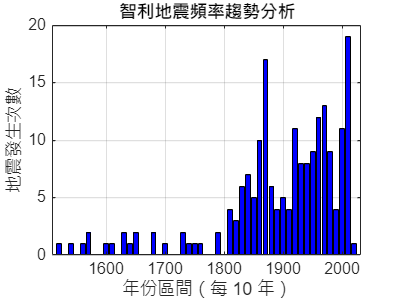


data = readtable('chile_earthquakes_1520-2024.xlsx', 'VariableNamingRule', 'preserve');

% 缺失年份就忽略
years = data.Year;
years = years(~isnan(years));

% 每10年一個級距
binWidth = 10; 
yearRange = min(years):binWidth:max(years);
yearly_count = histcounts(years, [yearRange, max(years) + binWidth]);

% 趨勢圖
figure;
bar(yearRange, yearly_count, 'FaceColor', 'b');
xlabel(['年份區間（每 ', num2str(binWidth), ' 年）']);
ylabel('地震發生次數');
title('智利地震頻率趨勢分析');
grid on;
set(gca, 'FontSize', 12);